# Linear Regression Model

## 1 Load the Data

x = load('ex2x.dat');
y = load('ex2y.dat');

**可视化数据**

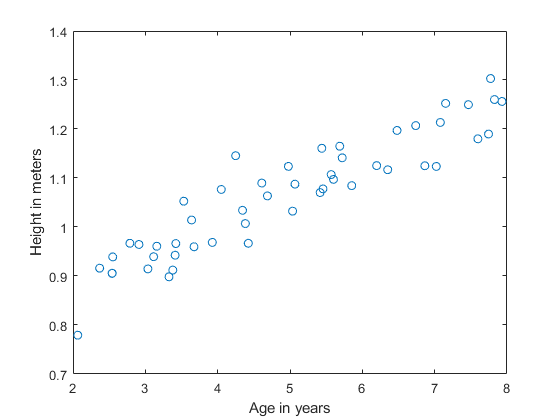

figure
plot(x,y,'o');
ylabel('Height in meters')
xlabel("Age in years")

## 2 Linear regression

% X矩阵加入一列，变为(length(y),2)
m = length(y)

m = 50

X = [ones(m,1),x]

X =     1.0000    2.0659
    1.0000    2.3684
    1.0000    2.5400
    1.0000    2.5421
    1.0000    2.5491
    1.0000    2.7867
    1.0000    2.9117
    1.0000    3.0356
    1.0000    3.1147
    1.0000    3.1582


% 初始化参数
theta = zeros(2,1);
theta(1)

ans = 0

theta(2)

ans = 0

% Gradient descent setting
iterate = 1500;  %迭代次数
alpha = 0.07;  %Learning rate

**采用梯度下降算法进行求解**

% 编写梯度下降算法GradientDescent

计算迭代次数

theta = GradientDescent(X,y,theta,alpha,iterate)

theta =     0.7502
    0.0639


**牛顿法求解线性回归**

[m,n] = size(X)

m = 50

n = 2

X(1,:)

ans =     1.0000    2.0659



% 初始参数
iterMax = 800;
sigma = 0.1

sigma = 0.1000

delta = 0.5;

theta = Newton(X,y,iterMax,sigma,delta)

## 3 Predicted Model

hold on %Plot new data without clearing old plot
plot(X(:,2),X*theta,'-')
legend('Training data','Linear Regression')

## 3 Understanding J($\theta$)

To get the best viewing results on your surface plot

J_vals = zeros(100,100);  %Initialize Jvals to 100×100 matrix
theta0_vals = linspace(-3,3,100);
theta1_vals = linspace(-1,1,100);
for i=1:length(theta0_vals)
    for j=1:length(theta1_vals)
        t = [theta0_vals(i);theta1_vals(j)];
        J_vals(i,j) = Lossfunction(t,X,y);
    end
end

% Plot the surface plot
%Because of the way meshgrids work in the surf command,we need to
% transpose J_vals before calling surf,or else the axes will be flipped
J_vals = J_vals';
figure;
surf(theta0_vals,theta1_vals,J_vals)
xlabel('\theta_0');
ylabel('\theta_1');

**Understand J('\theta')**

contour(theta0_vals,theta1_vals,J_vals,logspace(-2,2,15))
xlabel('\theta_0');
ylabel('\theta_1');